# Control and Instrumentation Lab Assignment 3

**SWARNENDU PAUL 19EE3FP18**

**Question.5.**

**A.**

The given closed loop system designed in SIMULINK is given in **"model.slx"**

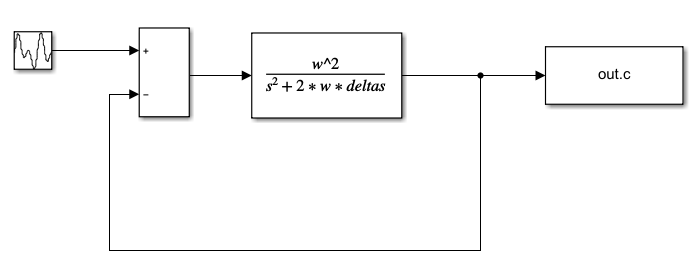

We will find the output response C(s) for 14 different values of $\delta$ from 0.2 to 1.5 keeping natural frequency $\omega_n$ fixed at 16 rad/sec . R(s) provided by the waveform generator is unit step input at $t=0$.

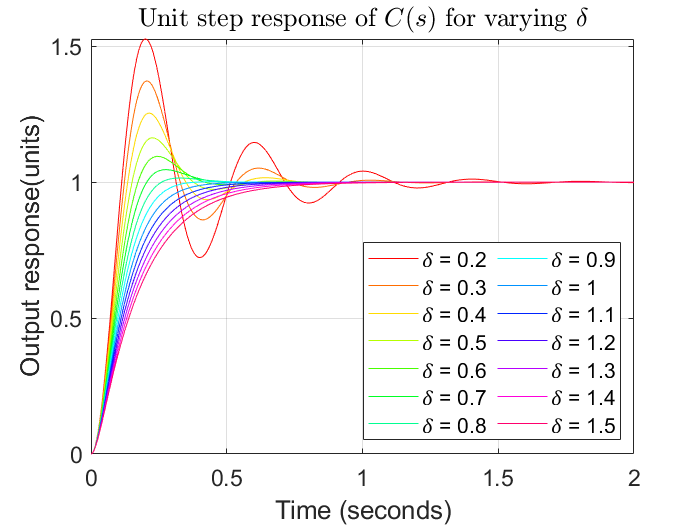

figure;
w=16;
d=0.2:0.1:1.5;
CM=hsv(14);
title("Unit step response of $C(s)$ for varying $\delta$",'Interpreter',"latex");
grid on;
xlabel("Time (seconds)");
ylabel("Output response(units)");
for i=1:14
    delta=d(i);
    a=sim("model.slx");
    plot(a.c,'color',CM(i,:),'DisplayName',strcat("𝛿 = ",num2str(delta)));
    hold on
end
hold off;
title("Unit step response of $C(s)$ for varying $\delta$",'Interpreter',"latex");
grid on;
xlabel("Time (seconds)");
ylabel("Output response(units)");
legend('NumColumns',2,'Location',"southeast");
set(gca,"FontSize",14);

As observed in the plot, as we increase damping ratio $\delta$, damping frequency of the output decreases. When $\delta=1$ the system is **critically damped**, As we increase $\delta$ system becomes **overdamped **and takes longer time to reach the final value.